# plot the Basic demographics JF and non-JF galaxies of he CJF project

## perliminaries


global DEFAULT_MATFILE_DIR
colors=brewermap(9,'Set1');

## load data


% load object table
load([ DEFAULT_MATFILE_DIR '\cosmic_jellyfish_objectTable.mat']);

% load galaxy properties
load([DEFAULT_MATFILE_DIR '\jf_galProperties_CJF.mat']);

## add additional data fields

massRatio=galProps.stellarMass./galProps.hostM200c;
redshifts=round(100.*illustris.utils.snap2redshift(galProps.snap))./100;

## Define JF

threshJF=16;
fprintf('JF Threshold set to %i and above. \n', threshJF);

JF Threshold set to 16 and above. 



maskJF=objectTable.score>=16;
maskNJF=objectTable.score<=5;

% list snaps and redshifts
snaps=unique(objectTable.snap);
zreds=round(100.*illustris.utils.snap2redshift(snaps))./100;


%% adress 3 strange objects

mm=galProps.hostM200c<1e11 & maskJF';
ind=find(mm);
maskJF2=maskJF;
maskJF2(mm)=false;

## plot some general info about the sample


nObject=height(objectTable);
fprintf('Total number of objects = %i \n',nObject);

Total number of objects = 80704 


fprintf('Total number of JF = %i (%4.2f %%) \n',sum(maskJF),sum(maskJF)/nObject*100);

Total number of JF = 4553 (5.64 %) 



mask100=objectTable.sim=="TNG100";
mask50=~mask100;
fprintf('TNG100 number of objects = %i (%4.2f %%) \n',sum(mask100),sum(mask100)/nObject*100);

TNG100 number of objects = 27094 (33.57 %) 


fprintf('TNG50 number of objects = %i (%4.2f %%) \n',sum(mask50),sum(mask50)/nObject*100);

TNG50 number of objects = 53610 (66.43 %) 



fprintf('TNG100 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask100),sum(maskJF & mask100)/sum(mask100)*100);

TNG100 number of JFs = 846 (3.12 %) 


fprintf('TNG50 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask50),sum(maskJF & mask50)/sum(mask50)*100);

TNG50 number of JFs = 3707 (6.91 %) 


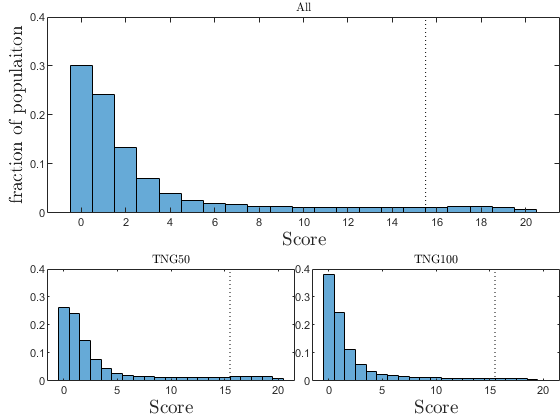


yl=[0 0.4];
% score histogram 
figure
t=tiledlayout(5,2);
nexttile([3 2])
histogram(objectTable.score,'normalization','probability')
ylim(yl)
%yl=ylim;
hold on
plot(15.5.*ones(size(yl)),yl,':k' )
xlabelmine('Score');
ylabelmine('fraction of populaiton');
titlemine('All');

nexttile([2 1])
histogram(objectTable.score(mask50),'normalization','probability')
%yl=ylim;
ylim(yl)
hold on
plot(15.5.*ones(size(yl)),yl,':k' )
xlabelmine('Score');
%ylabelmine('fraction of populaiton');
titlemine('TNG50');

nexttile([2 1])
histogram(objectTable.score(mask100),'normalization','probability')
%yl=ylim;
ylim(yl)
hold on
plot(15.5.*ones(size(yl)),yl,':k' )
xlabelmine('Score');
%ylabelmine('fraction of populaiton');
titlemine('TNG100');
t.TileSpacing='tight';
t.Padding='tight';


% Another version 
yl=[0 0.4];
% score histogram 
figure
t=tiledlayout(2,1)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


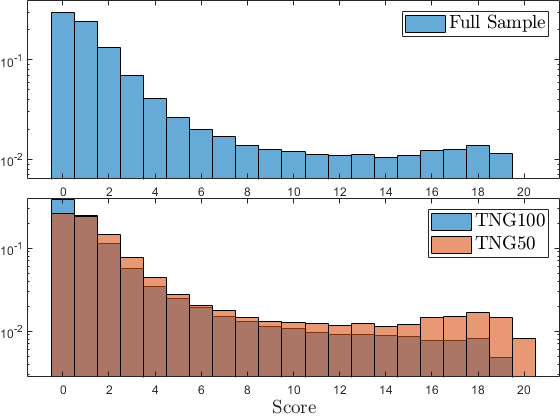

nexttile
histogram(objectTable.score,'normalization','probability')
ylim(yl)
%yl=ylim;
hold on
plot(15.5.*ones(size(yl)),yl,':k' )
legend("Full Sample",'Interpreter','latex','FontSize',14)
%xlabelmine('Score');
set(gca,'Yscale','log')
%ylabelmine('fraction of populaiton');
%titlemine('All');

nexttile
histogram(objectTable.score(mask100),'normalization','probability')
hold on
histogram(objectTable.score(mask50),'normalization','probability')

%yl=ylim;
ylim(yl)
hold on
plot(15.5.*ones(size(yl)),yl,':k' )
legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',14)
set(gca,'Yscale','log')
xlabelmine('Score');
%ylabelmine('fraction of populaiton');
%titlemine('TNG50');

%t.YLabel('fraction of populaiton');
t.TileSpacing='tight';
t.Padding='tight';

## plot stellar mass and host mass functions

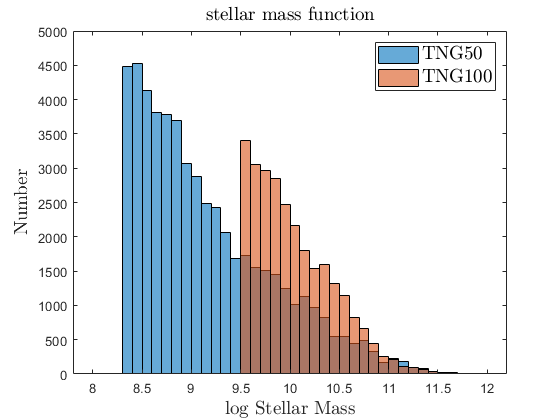

bins=8.0:0.1:12;
figure
histogram(log10(galProps.galStellarMass(mask50)),bins)
hold on
histogram(log10(galProps.galStellarMass(mask100)),bins)
legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',14)
xlabelmine('log Stellar Mass');
ylabelmine('Number');
titlemine('stellar mass function');

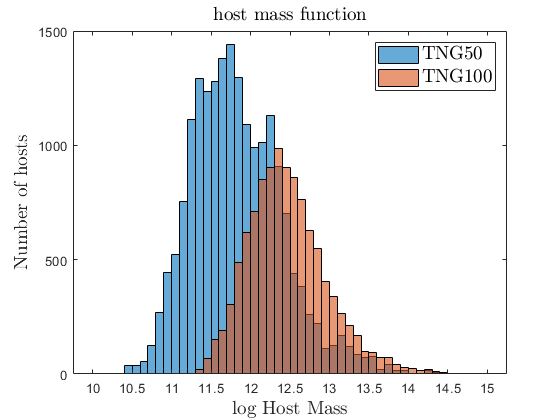


[~,ia,~]=unique(galProps.hostTag);
hmass=galProps.hostM200c(ia);
hsim=galProps.sim(ia);

bins=10:0.1:15;
figure
histogram(log10(hmass(hsim=="TNG50")),bins)
hold on
histogram(log10(hmass(hsim=="TNG100")),bins)
legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',14)
xlabelmine('log Host Mass');
ylabelmine('Number of hosts');
titlemine("host mass function");

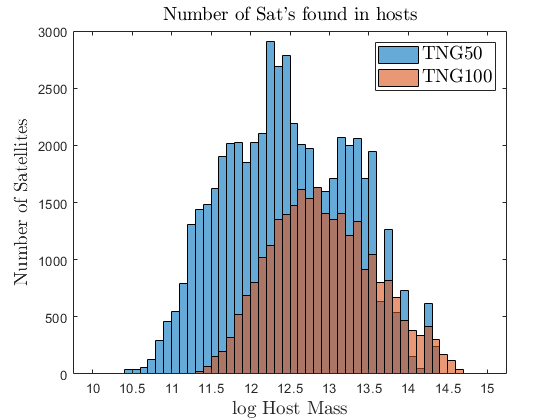



bins=10:0.1:15;
figure
histogram(log10(galProps.hostM200c(mask50)),bins)
hold on
histogram(log10(galProps.hostM200c(mask100)),bins)
legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',14)
xlabelmine('log Host Mass');
ylabelmine('Number of Satellites');
titlemine("Number of Sat's found in hosts");

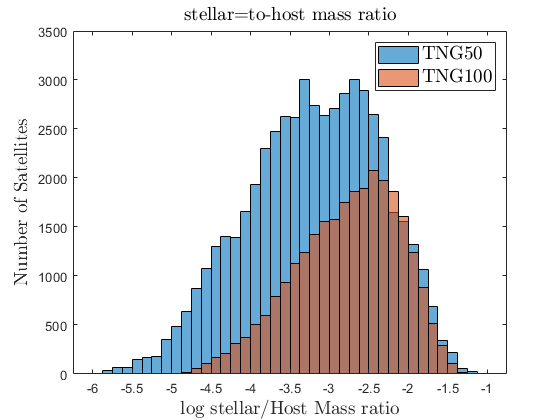




bins=-6:0.125:-1;
figure
histogram(log10(massRatio(mask50)),bins)
hold on
histogram(log10(massRatio(mask100)),bins)
legend(["TNG50","TNG100"],'Interpreter','latex','FontSize',14)
xlabelmine('log stellar/Host Mass ratio');
ylabelmine('Number of Satellites');
titlemine("stellar=to-host mass ratio");



figure
hs=histogram(galProps.snap(mask100),30.5:1:99.5);
hold on
histogram(galProps.snap(mask50),30.5:1:99.5)
yl=ylim;
ind=find(hs.Values>0);


for i=1:length(ind)
    
    xx=0.5.*sum(hs.BinEdges(ind(i)-1:ind(i)));
    
    yy=hs.Values(ind(i))+0.06.*diff(yl);
    zz=round(100*illustris.utils.snap2redshift(xx+1))/100;
    
    text(xx,yy,num2str(zz))
end


legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',12,'Location','northwest')
xlabelmine('snaps');
ylabelmine('Number of Satellites');
titlemine("snapshot/redshift distribution");



% 
% 
% figure
% histogram(redshifts(mask100),be)
% hold on
% histogram(redshifts(mask50),be)
% legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',14)
% xlabelmine('snaps');
% ylabelmine('Number of Satellites');
% titlemine("stellar=to-host mass ratio");


## examine samples by snapshots and simulations

% % snapshot bins
% hostMassBins=10.^(10:15);
% stellarMassBins=10.^(8:1:12.5);
% zredBins=[0:0.25:0.75 1.0 1.5 2.1]; %0:0.2001:2.1;
% 
% massRatBins=10.^(-6:0.5:-1);
% 
% 
% 
% % bin Indices arrays
% hmBI=discretize(galProps.hostM200c,hostMassBins);
% smBI=discretize(galProps.stellarMass,stellarMassBins);
% mrBI=discretize(massRatio,massRatBins);
% zrBI=discretize(redshifts,zredBins);
% 
% % tags
% simTags=unique(galProps.sim);
% simTags(3)=join([simTags(1) '\&' simTags(2)]);

## fraction vs. stellar mass in halo mass bins

hostMassBins=10.^(10:15);
stellarMassBins=10.^(8:0.5:12.5);
hmBI=discretize(galProps.hostM200c,hostMassBins);
smBI=discretize(galProps.stellarMass,stellarMassBins);

jellyfish.utils.plot_demographics(maskJF,smBI,stellarMassBins,hmBI,hostMassBins,...
    'log','label','stellar mass','legtag','$M_\mathrm{h}=$');

jellyfish.utils.plot_demographics_2sims(maskJF,smBI,stellarMassBins,hmBI,hostMassBins,mask50,...
    'log','label','stellar mass','legtag','$M_\mathrm{h}=$');


## fraction vs. host mass in Stellar mass bins

hostMassBins=10.^(10:15);
stellarMassBins=10.^(8:1:12.5);
hmBI=discretize(galProps.hostM200c,hostMassBins);
smBI=discretize(galProps.stellarMass,stellarMassBins);

jellyfish.utils.plot_demographics(maskJF,hmBI,hostMassBins,smBI,stellarMassBins,...
    'log','label','host mass','legtag','$M_\mathrm{\ast}=$');

jellyfish.utils.plot_demographics_2sims(maskJF,hmBI,hostMassBins,smBI,stellarMassBins,mask50,...
    'log','label','host mass','legtag','$M_\mathrm{\ast}=$');

## fraction vs. mass ratio in Stellar mass bins

massRatBins=10.^(-6:0.5:-2);
mrBI=discretize(massRatio,massRatBins);
stellarMassBins=10.^(8:1:12.5);
smBI=discretize(galProps.stellarMass,stellarMassBins);

jellyfish.utils.plot_demographics(maskJF,mrBI,massRatBins,smBI,stellarMassBins,...
    'log','label','mass ratio','legtag','$M_\mathrm{\ast}=$');
jellyfish.utils.plot_demographics_2sims(maskJF,mrBI,massRatBins,smBI,stellarMassBins,mask50,...
    'log','label','mass ratio','legtag','$M_\mathrm{\ast}=$');

stellarMassBins=10.^(8:0.5:12.5);
smBI=discretize(galProps.stellarMass,stellarMassBins);
massRatBins=10.^(-6:1:-2);
mrBI=discretize(massRatio,massRatBins);
jellyfish.utils.plot_demographics(maskJF,smBI,stellarMassBins,mrBI,massRatBins,...
    'log','label','stellar mass','legtag','$M_\mathrm{sat}/M_\mathrm{h}$');
jellyfish.utils.plot_demographics_2sims(maskJF,smBI,stellarMassBins,mrBI,massRatBins,mask50,...
    'log','label','stellar mass','legtag','$M_\mathrm{sat}/M_\mathrm{h}$');

## fraction vs. mass rtion in host mass bins

massRatBins=10.^(-6:0.5:-2);
mrBI=discretize(massRatio,massRatBins);
hostMassBins=10.^(10:15);
hmBI=discretize(galProps.hostM200c,hostMassBins);

jellyfish.utils.plot_demographics(maskJF,mrBI,massRatBins,hmBI,hostMassBins,...
    'log','label','mass ratio','legtag','$M_\mathrm{h}=$');

jellyfish.utils.plot_demographics_2sims(maskJF,mrBI,massRatBins,hmBI,hostMassBins,mask50,...
    'log','label','mass ratio','legtag','$M_\mathrm{h}=$');

## fraction vs. redshift in host mass bins

hostMassBins=10.^(10:15);
hmBI=discretize(galProps.hostM200c,hostMassBins);
zredBins=[0 0.05:0.1:0.55 0.75 1.25 1.75 2.2];
zx=[0:0.1:0.5 0.7 1 1.5 2];
zrBI=discretize(redshifts,zredBins);
jellyfish.utils.plot_demographics(maskJF,zrBI,zredBins,hmBI,hostMassBins,'xx',zx,...
    'label','redshift','legtag','$M_\mathrm{h}=$');

jellyfish.utils.plot_demographics(maskJF2,zrBI,zredBins,hmBI,hostMassBins,'xx',zx,...
    'label','redshift','legtag','$M_\mathrm{h}=$');

jellyfish.utils.plot_demographics_2sims(maskJF,zrBI,zredBins,hmBI,hostMassBins,mask50,'xx',zx,...
    'label','redshift','legtag','$M_\mathrm{h}=$');
jellyfish.utils.plot_demographics_2sims(maskJF2,zrBI,zredBins,hmBI,hostMassBins,mask50,'xx',zx,...
    'label','redshift','legtag','$M_\mathrm{h}=$');

% jellyfish.utils.plot_demographics(maskJF,zrBI,zredBins,hmBI,hostMassBins,'xx',zx,...
%     'label','redshift','legtag','$M_\mathrm{h}=$','tng50',galProps.sim=="TNG50");
% 
% jellyfish.utils.plot_demographics(maskJF,zrBI,zredBins,hmBI,hostMassBins,'xx',zx,...
%     'label','redshift','legtag','$M_\mathrm{h}=$','tng100',galProps.sim=="TNG100");

## fraction vs. stellarmass, hostmass mass ration  in redshift bins

%zredBins=[0 0.25 0.501 0.75 1.25 1.75 2.2];
zredBins=[0 0.501  1.25 2.2];
%zx=[0  1 2];

zrBI=discretize(redshifts,zredBins);
zleg=["$z=0-0.5$" "$z=0.5-1$" "$z=1-2$" ];


% stellar mass 
stellarMassBins=10.^(8:0.5:12.5);
smBI=discretize(galProps.stellarMass,stellarMassBins);

jellyfish.utils.plot_demographics(maskJF,smBI,stellarMassBins,zrBI,zredBins,...
    'log','label','stellar mass','legend',zleg);
% jellyfish.utils.plot_demographics_2sims(maskJF,smBI,stellarMassBins,zrBI,zredBins,mask50,...
%      'log','label','stellar mass','legend',zleg);

% host mass
hostMassBins=10.^(10:15);
hmBI=discretize(galProps.hostM200c,hostMassBins);

jellyfish.utils.plot_demographics(maskJF,hmBI,hostMassBins,zrBI,zredBins,...
    'log','label','host mass','legend',zleg,'cind',[1:5 7]);
jellyfish.utils.plot_demographics(maskJF2,hmBI,hostMassBins,zrBI,zredBins,...
    'log','label','host mass','legend',zleg,'cind',[1:5 7]);

% jellyfish.utils.plot_demographics_2sims(maskJF,hmBI,hostMassBins,zrBI,zredBins,mask50,...
%     'log','label','host mass','legend',zleg,'cind',[1:5 7]);

% mass ratio 
massRatBins=10.^(-6:0.5:-2);
mrBI=discretize(massRatio,massRatBins);

jellyfish.utils.plot_demographics(maskJF,mrBI,massRatBins,zrBI,zredBins,...
    'log','label','log mass ratio','legend',zleg,'cind',[1:5 7]);
% jellyfish.utils.plot_demographics_2sims(maskJF,mrBI,massRatBins,zrBI,zredBins,mask50,...
%     'log','label','log mass ratio','legend',zleg,'cind',[1:5 7]);


% breakup by sim
% stellar mass 
stellarMassBins=10.^(8:0.25:12.5);
smBI=discretize(galProps.stellarMass,stellarMassBins);

jellyfish.utils.plot_demographics_2sims(maskJF,smBI,stellarMassBins,zrBI,zredBins,mask50,...
    'log','label','stellar mass','legend',zleg,'cind',[1:5 7]);


% host mass
hostMassBins=10.^(10:15);
hmBI=discretize(galProps.hostM200c,hostMassBins);

jellyfish.utils.plot_demographics_2sims(maskJF,hmBI,hostMassBins,zrBI,zredBins,mask50,...
    'log','label','host mass','legend',zleg,'cind',[1:5 7]);

% mass ratio 
massRatBins=10.^(-6:0.5:-2);
mrBI=discretize(massRatio,massRatBins);

jellyfish.utils.plot_demographics_2sims(maskJF,mrBI,massRatBins,zrBI,zredBins,mask50,...
    'log','label','host mass','legend',zleg,'cind',[1:5 7]);